#  PMSG (Permanent Magnet Synchronous Generator) Wind Power System

## **Before you get started**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**.  Alternatively, select **Hide Code **using the icon   at the top right of the Live Editor pane.

Some interactions require basic MATLAB familiarity. If you need a refresher, MATLAB Onramp is a free, two-hour tutorial that covers the essentials.[](https://www.mathworks.com/learn/tutorials/matlab-onramp.html)

Work through the sections in order. Some sections use variables created earlier, so running sections out of sequence may produce errors.

## 1. Introduction

A Type 4 wind power system, also known as a full-converter wind turbine system, is a modern wind energy generation system where the Permanent Magnet Synchronous Generator (PMSG) is fully decoupled from the grid using a back-to-back power converter. Unlike Type 1 and Type 2 systems, which rely on direct grid connection, and Type 3 systems, which use partial power conversion, Type 4 systems convert 100% of the generated power through power electronics. This configuration allows for wide-speed operation, full reactive power control, and enhanced grid compliance. The system consists of a wind turbine, a PMSG (or squirrel-cage induction generator), a rectifier-inverter power converter and a control system. Type 4 wind turbines are commonly used in offshore and large-scale onshore wind farms, where grid stability, variable-speed operation, and high energy efficiency are critical.

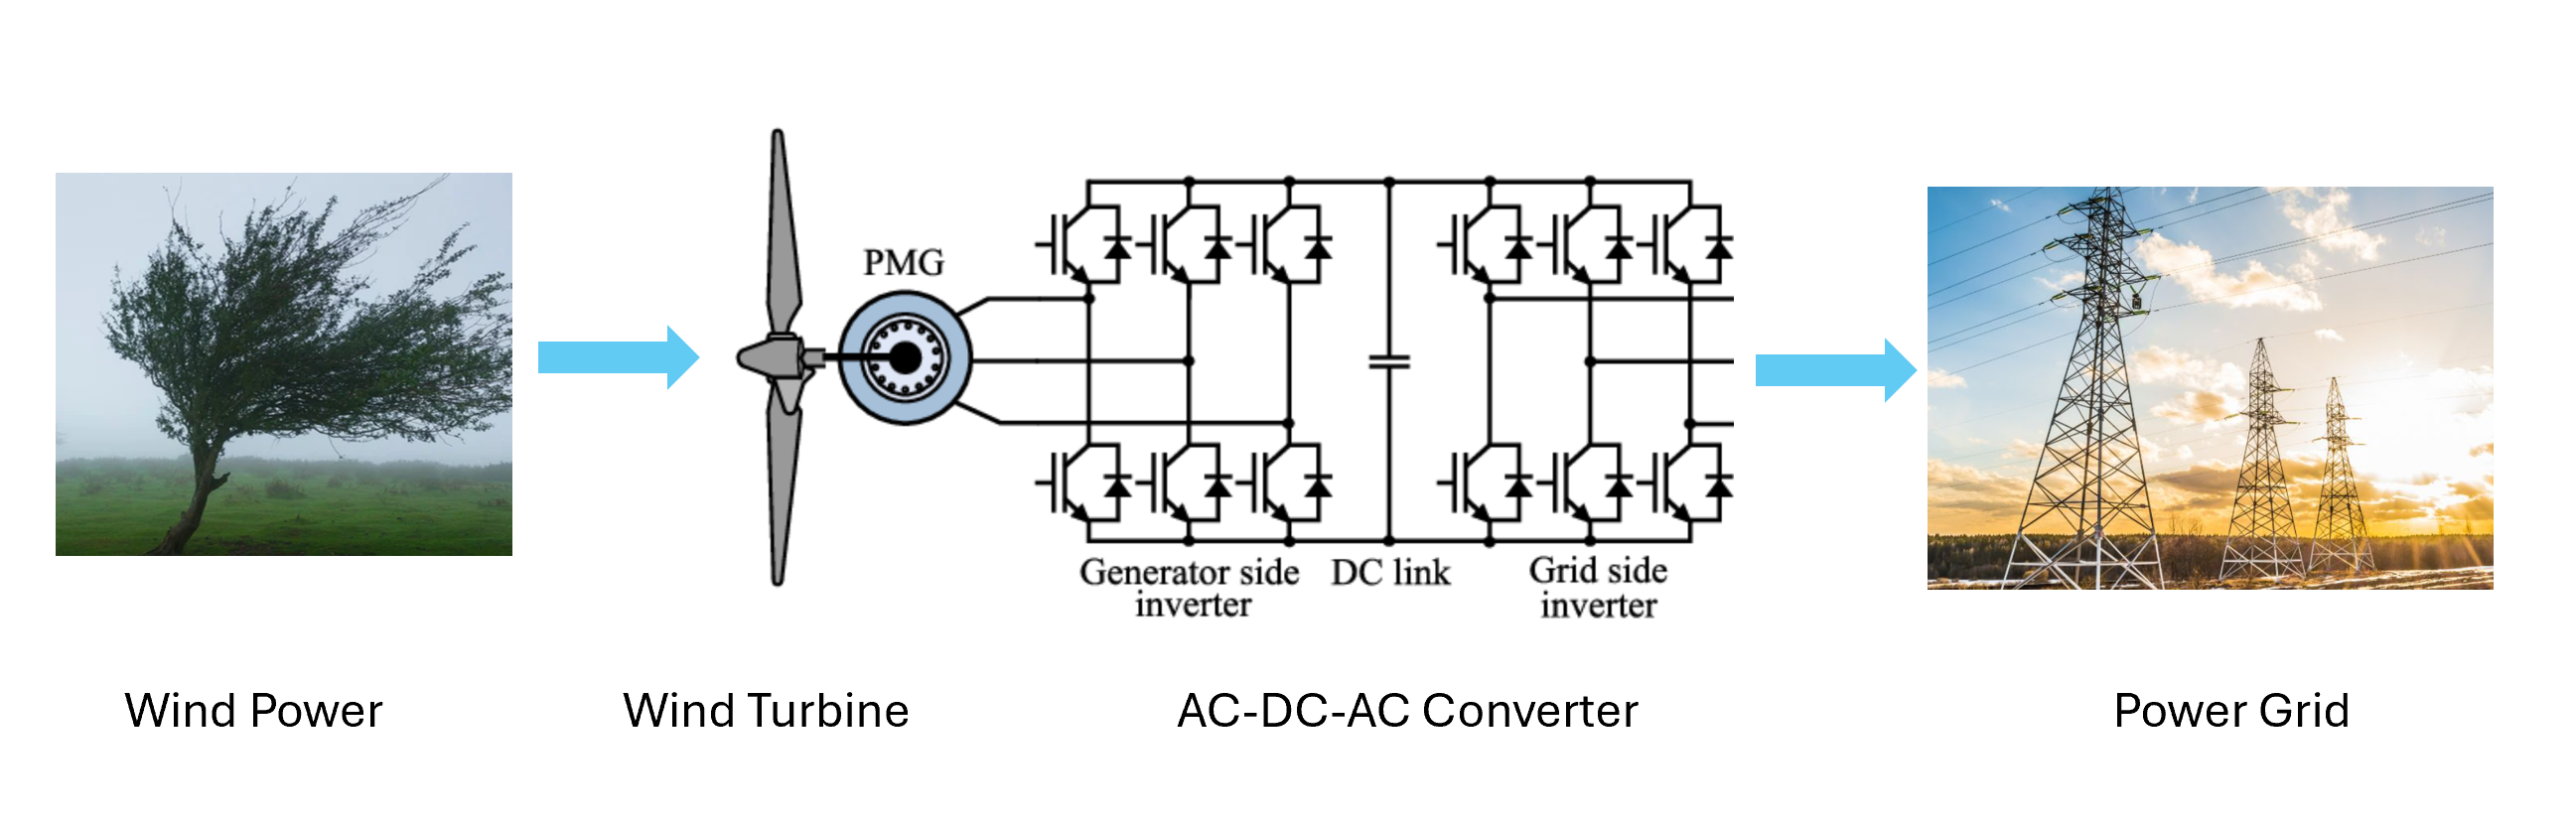

The structure of the PMSG wind power system 

The following table details the main differences between the four types of wind power systems.

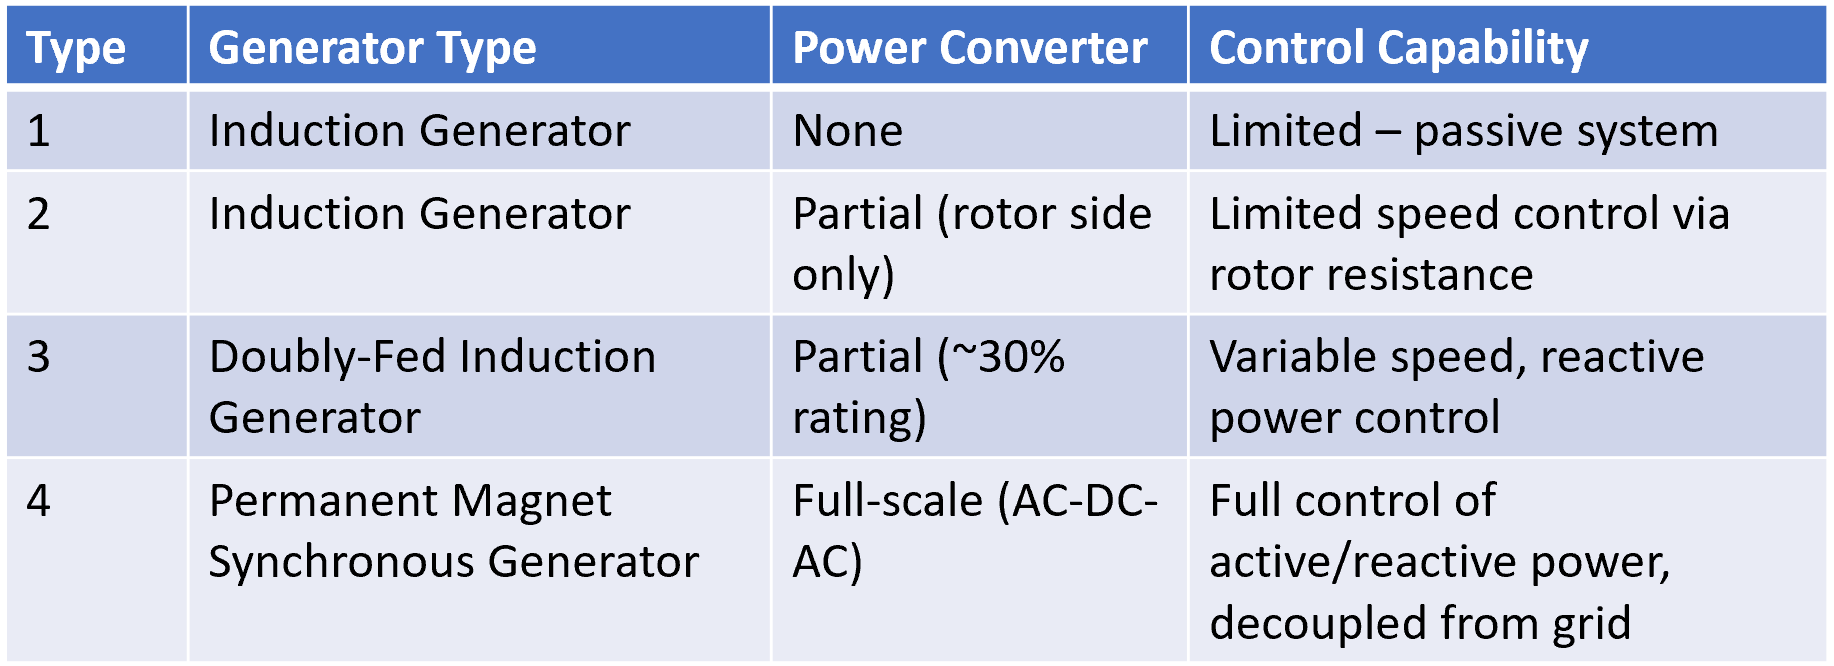

All four types of wind power systems

This activity focuses on four control and simulation tasks:

- Wind turbine simulation. 

- PMSG rotating speed control.

- DC-bus voltage control.

- Independent active and reactive power control.

By the end of this activity, you should be able to explain how generator speed control, DC-bus regulation, and reactive-power control work together in a Type 4 wind turbine system.

## 2. Model Layout Overview

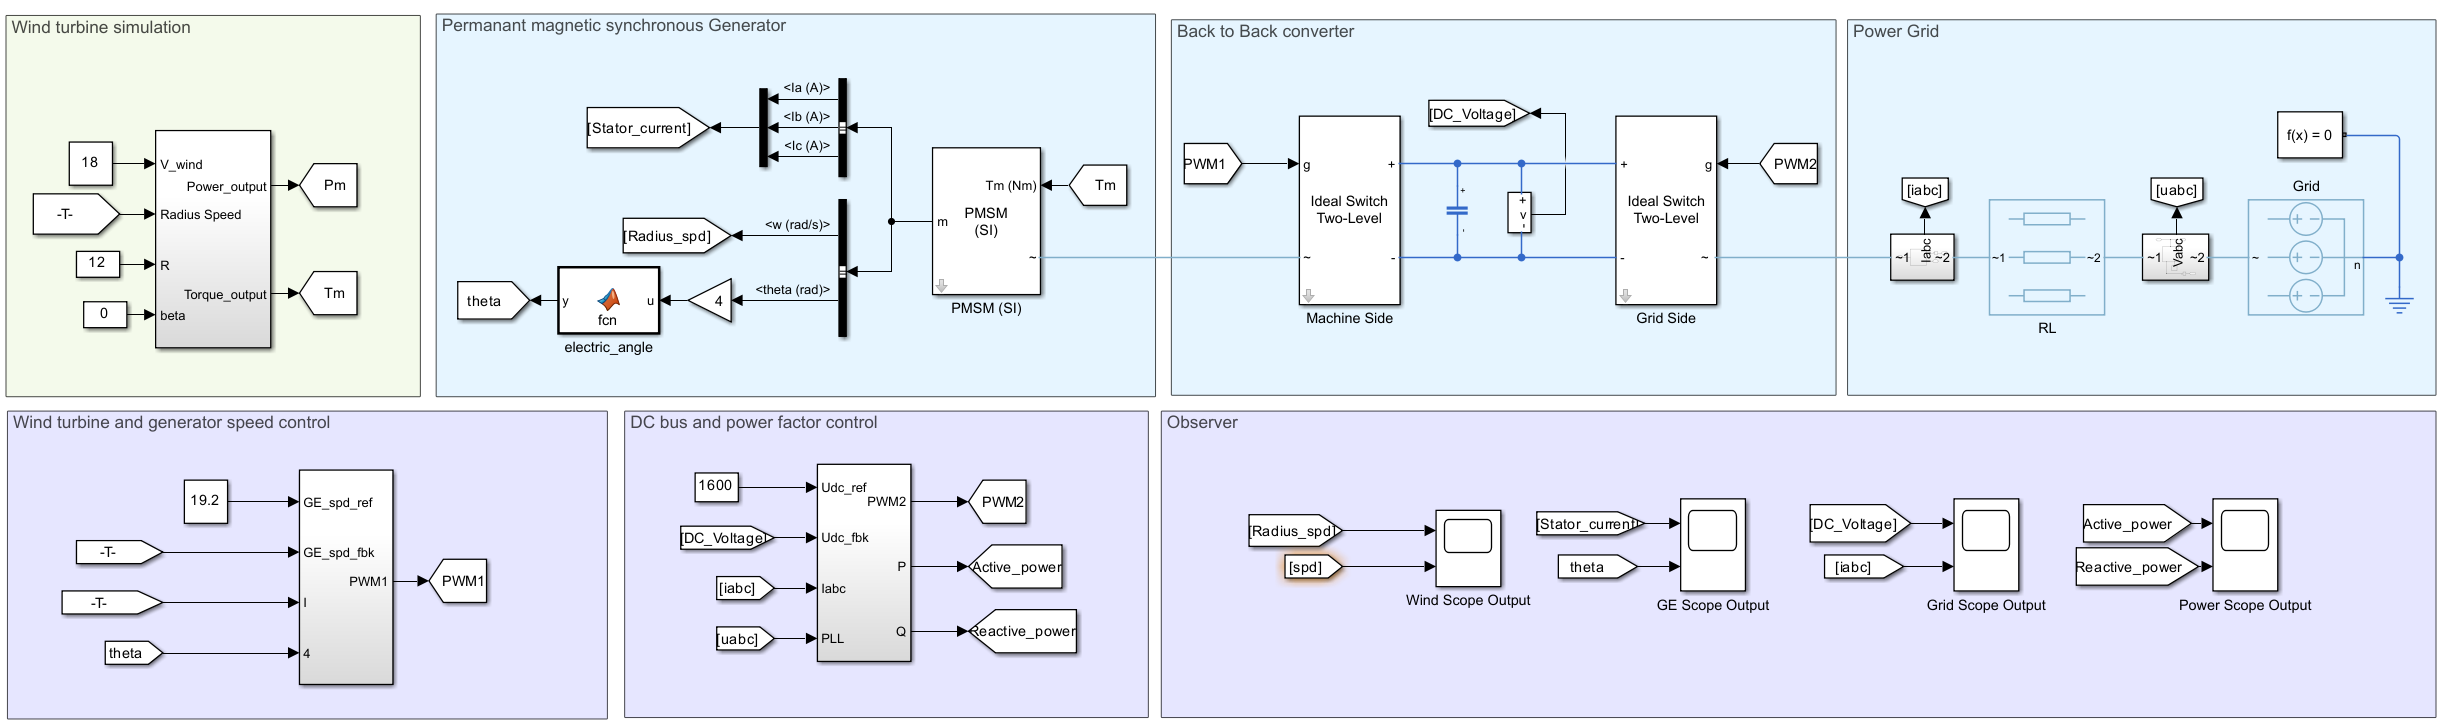

   PMSG-Wind Power

 
open_system("Models/newnewPMSG.slx")

## 3. Simulation Results Overview

**Task 1. **Before running, predict which variables should change quickly and which should settle slowly. Then click Run and inspect the initial simulation results. The simulation may take a few minutes.

 
disp("Please wait for the simulation to finish. This may take a few minutes")
runmodel();
disp("Simulation complete. You can now analyze the results")

The rest of the activity examines each control function separately, then connects the results back to system-level performance:

- Wind turbine model. 

- PMSG rotating speed control.

- DC-bus voltage control.

- Reactive power control.

### 3.1. Wind turbine model

The following block represents the wind turbine. Here, Pm is mechanical power output and Tm is mechanical torque output.

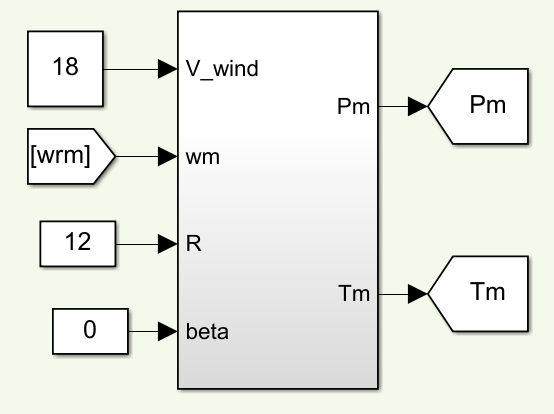

Wind speed (V_wind), turbine radius (R), and rotational speed (wm) determine the mechanical power and torque output.

**Task 2. **Before changing the inputs, predict how wind speed and rotational speed should affect turbine power. Then adjust the parameters and compare the output with your prediction.

Vwind=8.7;
Wm=13.4;
Radius=7.4;
 
open_system('Models/turbine_simscape.slx');
set_param('turbine_simscape/Constant', 'Value', num2str(Vwind));
set_param('turbine_simscape/Constant1', 'Value', num2str(Wm));
set_param('turbine_simscape/Constant5', 'Value', num2str(Radius));

warning('off','All')
simOut = sim('Models/turbine_simscape.slx'); 
out=simOut;

turbine_data = out.turbine;
time = turbine_data.time; 


signal1 = turbine_data.signals(1).values; 
signal2 = turbine_data.signals(2).values; 

figure('Position', [100, 100, 1000, 800]); 

yyaxis left
plot(time, signal1, 'LineWidth', 1.5); 
hold on;
yyaxis right
plot(time, signal2, 'LineWidth', 1.5);
hold off;
title('turbine Scope Output');
xlabel('Time (s)');
ylabel('Signal Value');
legend('Power', 'Torque');
grid on;
ax = gca;
yyaxis(ax,'left')
ylabel('Power')
yyaxis(ax,'right')
ylabel('Torque')
close_system('Models/turbine_simscape.slx',1);

### 3.2. PMSG Speed Control

In this section, you will need to make changes directly in the model itself. Click the button below to open the model and become familiar with it.

 
open_system('Models/newnewPMSG.slx');

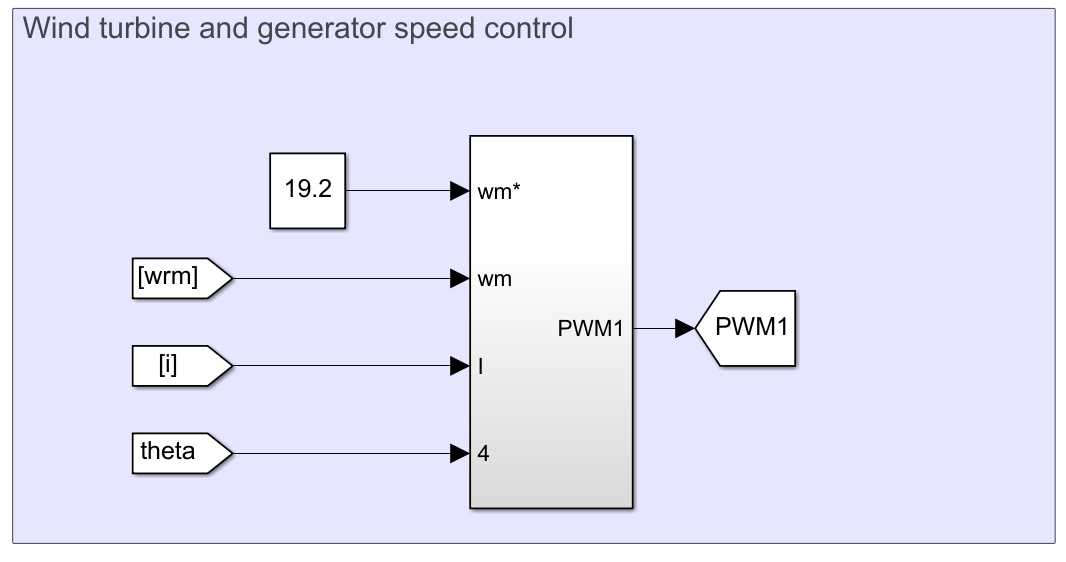

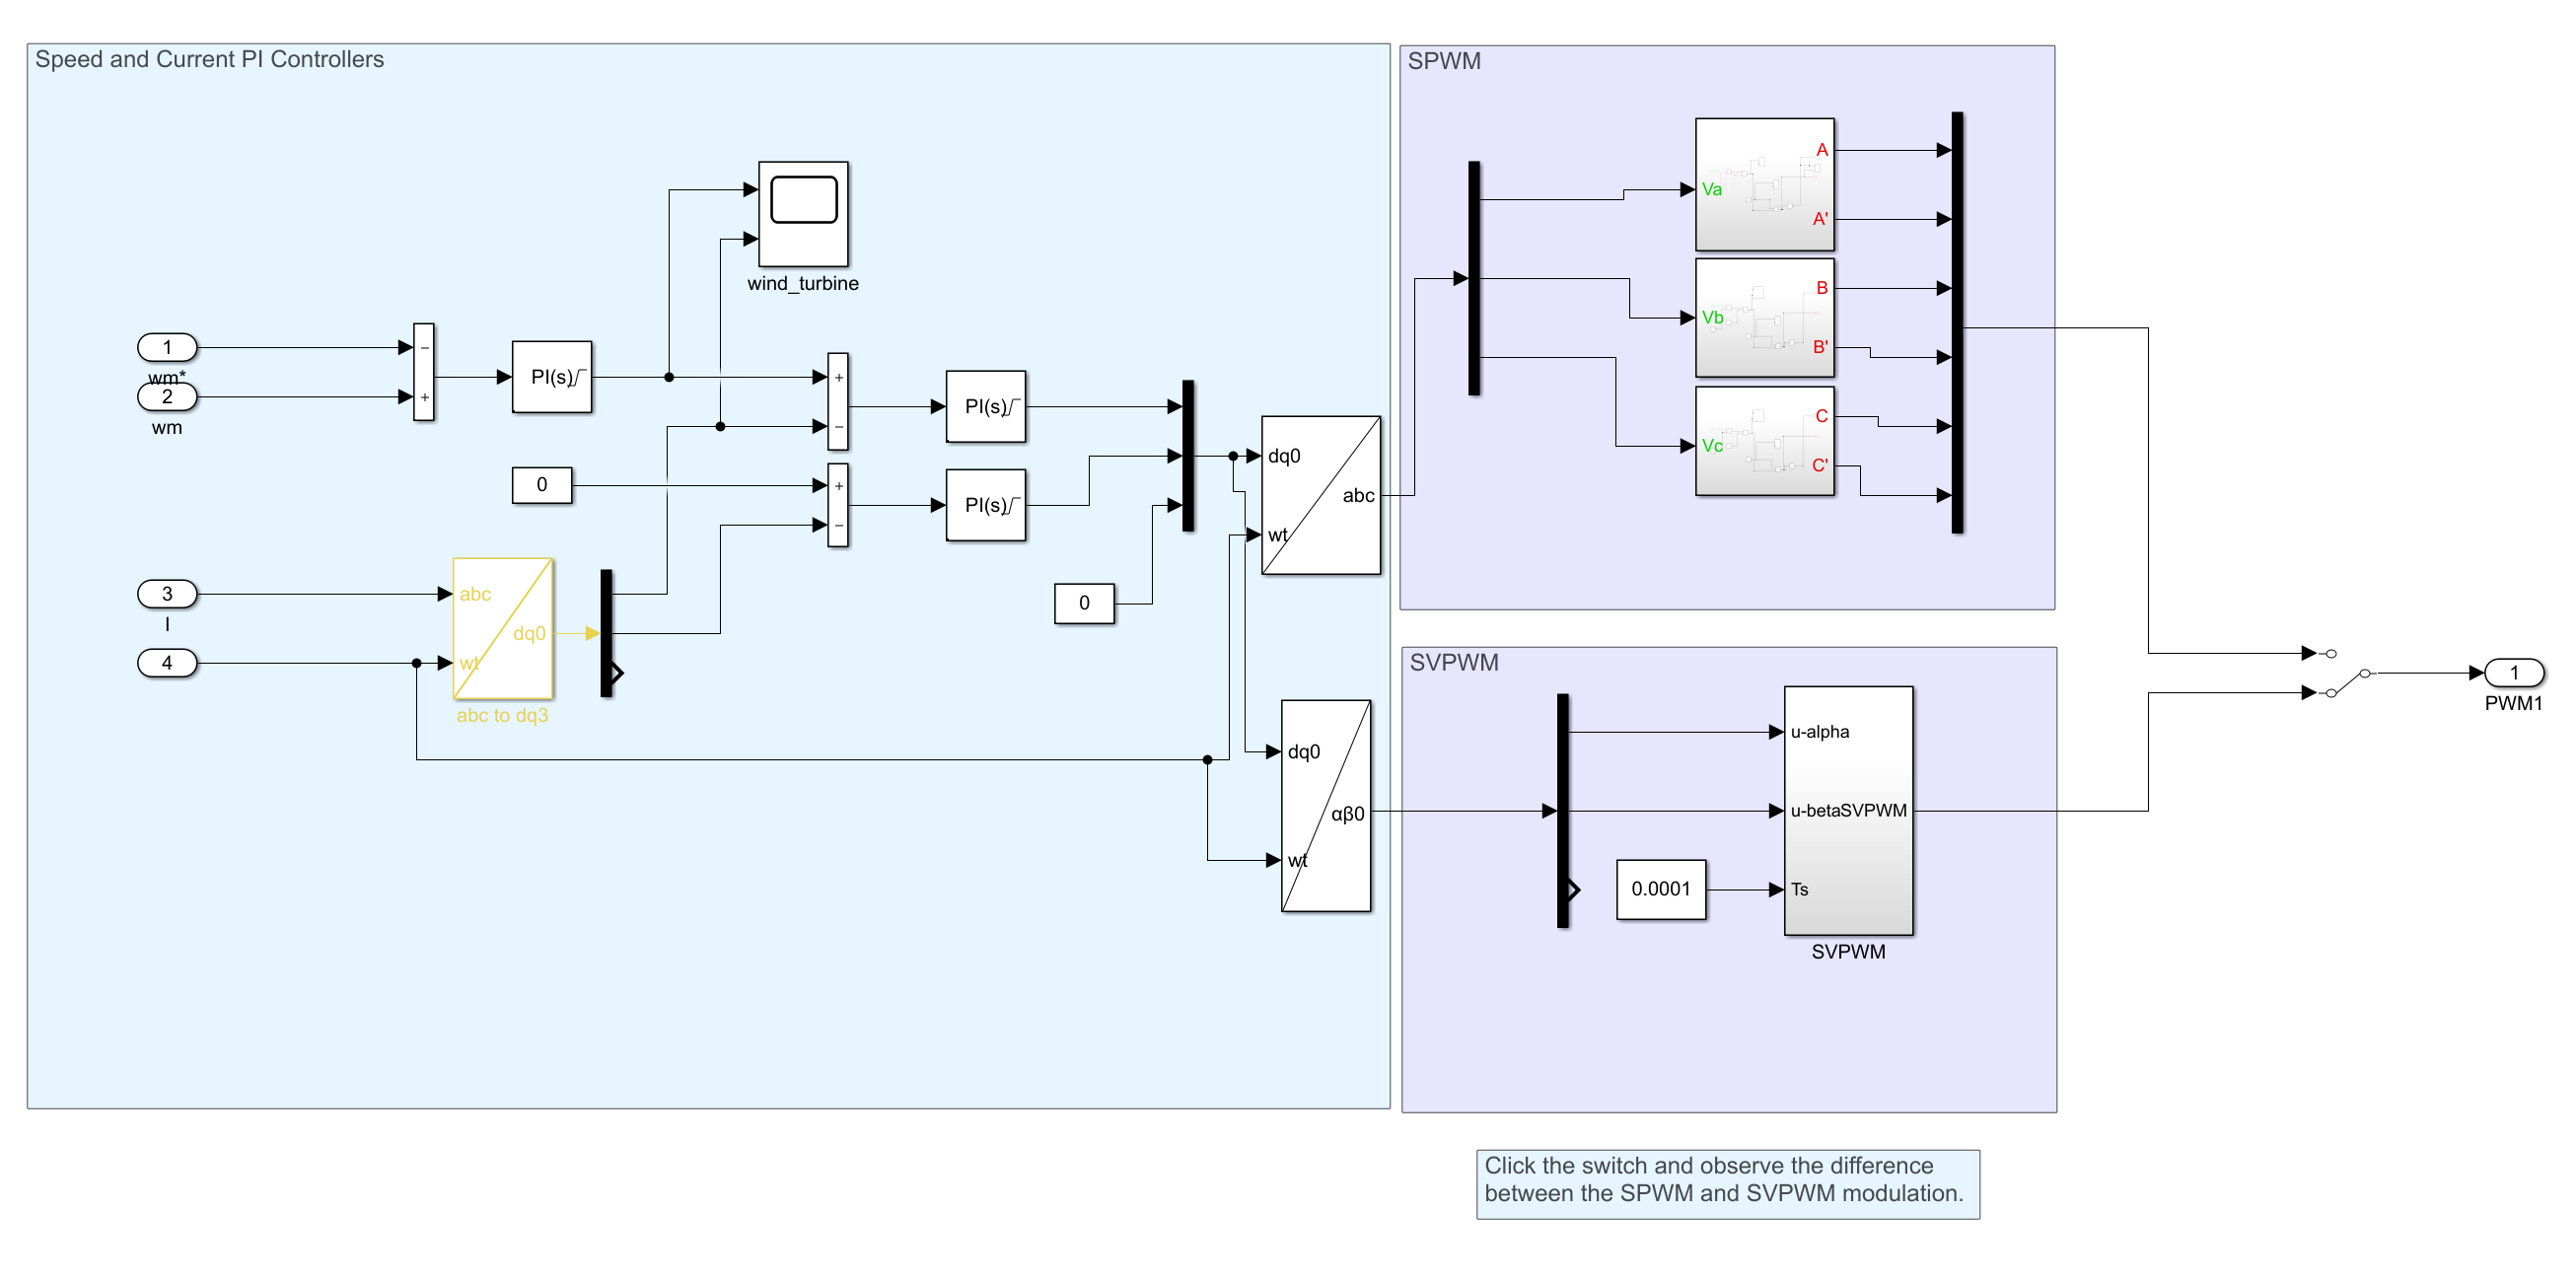

The structure of the PMSG speed controllers 

**Task 3. **Use the slider below to change the target generator rotational speed (GE_spd_ref). Compare the response using settling behavior, ripple, and tracking accuracy.

GE_spd_ref=18.9;
open_system('Models/newnewPMSG.slx');
set_param('newnewPMSG/Constant1', 'Value', num2str(GE_spd_ref));
 
runmodel();

Try the two modulation methods by clicking the switch block. Compare their performance using settling behavior, ripple, and tracking accuracy.

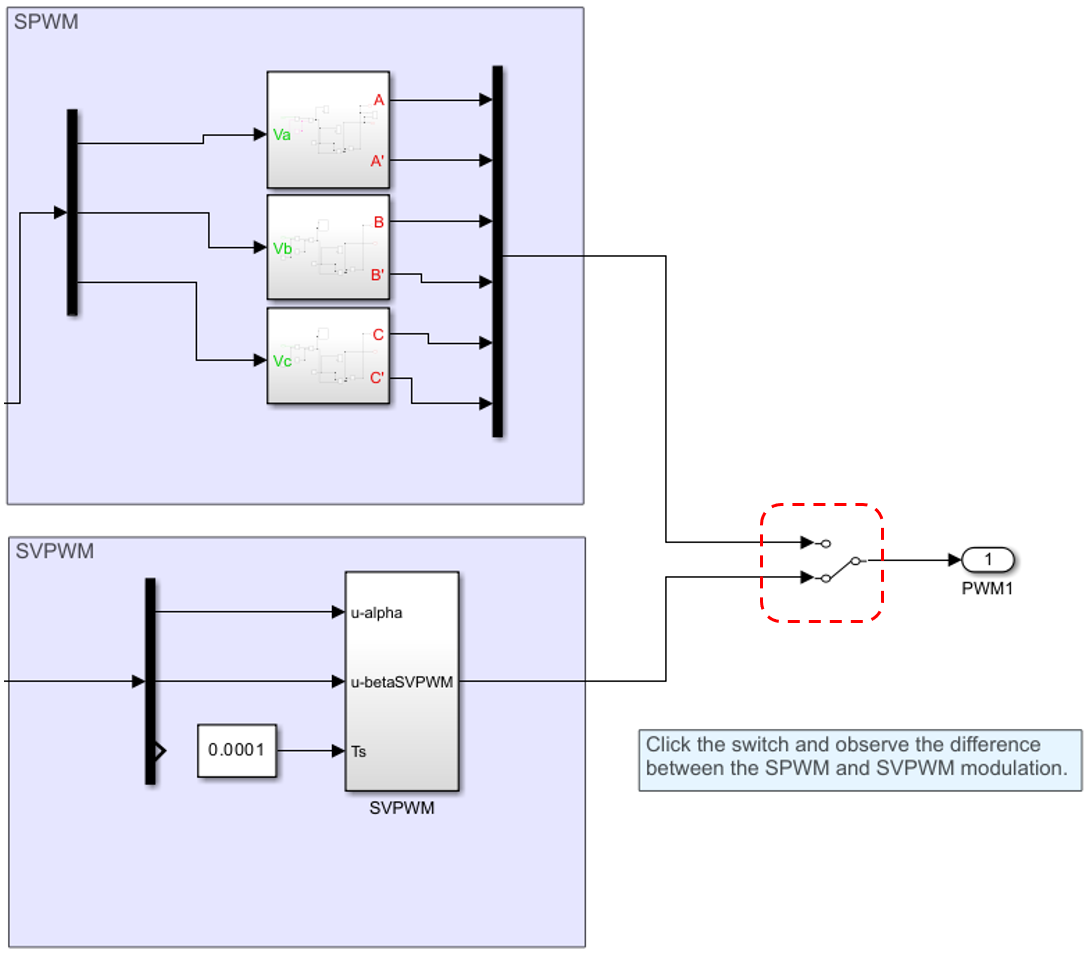

**Question: **What happens when wm is changed to a value below 19? Which model parameter or control setting would you change to resolve the issue?

showpic1(false);

### 3.3. DC Bus Control and Power Factor Control

The DC-bus in a wind power conversion system (especially in a Type 4 topology) acts as the energy buffer between the generator-side converter and the grid-side converter. It holds the intermediate DC voltage that links the AC-DC and DC-AC conversion stages.

Why do we control the DC-bus voltage?

- To ensure stable power transfer between the generator and the grid.

- To protect the converter components from overvoltage or undervoltage.

- To maintain sufficient voltage headroom for proper PWM operation of the inverter.

Why is the DC-bus voltage adjustable?

- It can be tuned depending on system requirements such as power level, grid voltage, and control bandwidth.

- In some systems, a higher DC-bus voltage may improve efficiency and reduce current stress on switching devices.

- During startup or fault conditions, adjusting the reference DC-bus voltage helps maintain system stability and enables safe operation.

- Designers may also adjust it based on the capacitor size, energy storage capability, or desired dynamic response.

In the Simulink model, changing the DC-bus reference lets you evaluate whether the control loop regulates voltage quickly and robustly under changing load or generation conditions.

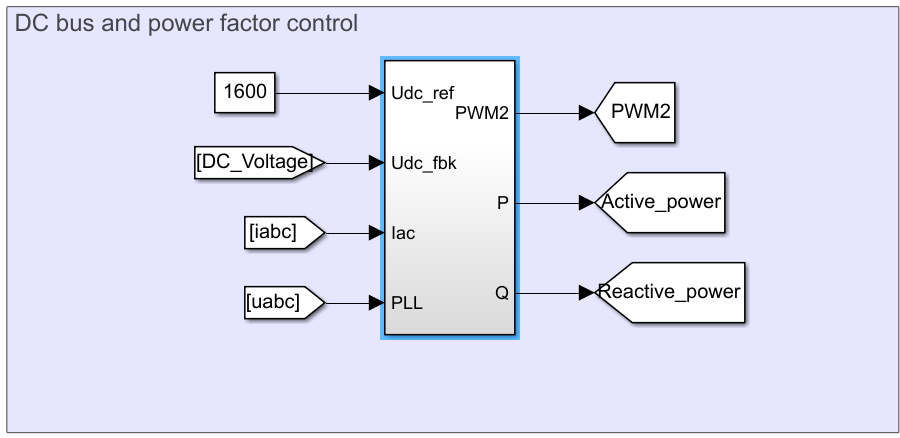

Before changing Udc and the initial capacitor voltage, predict how the DC-bus transient response should change. Then apply the following settings:

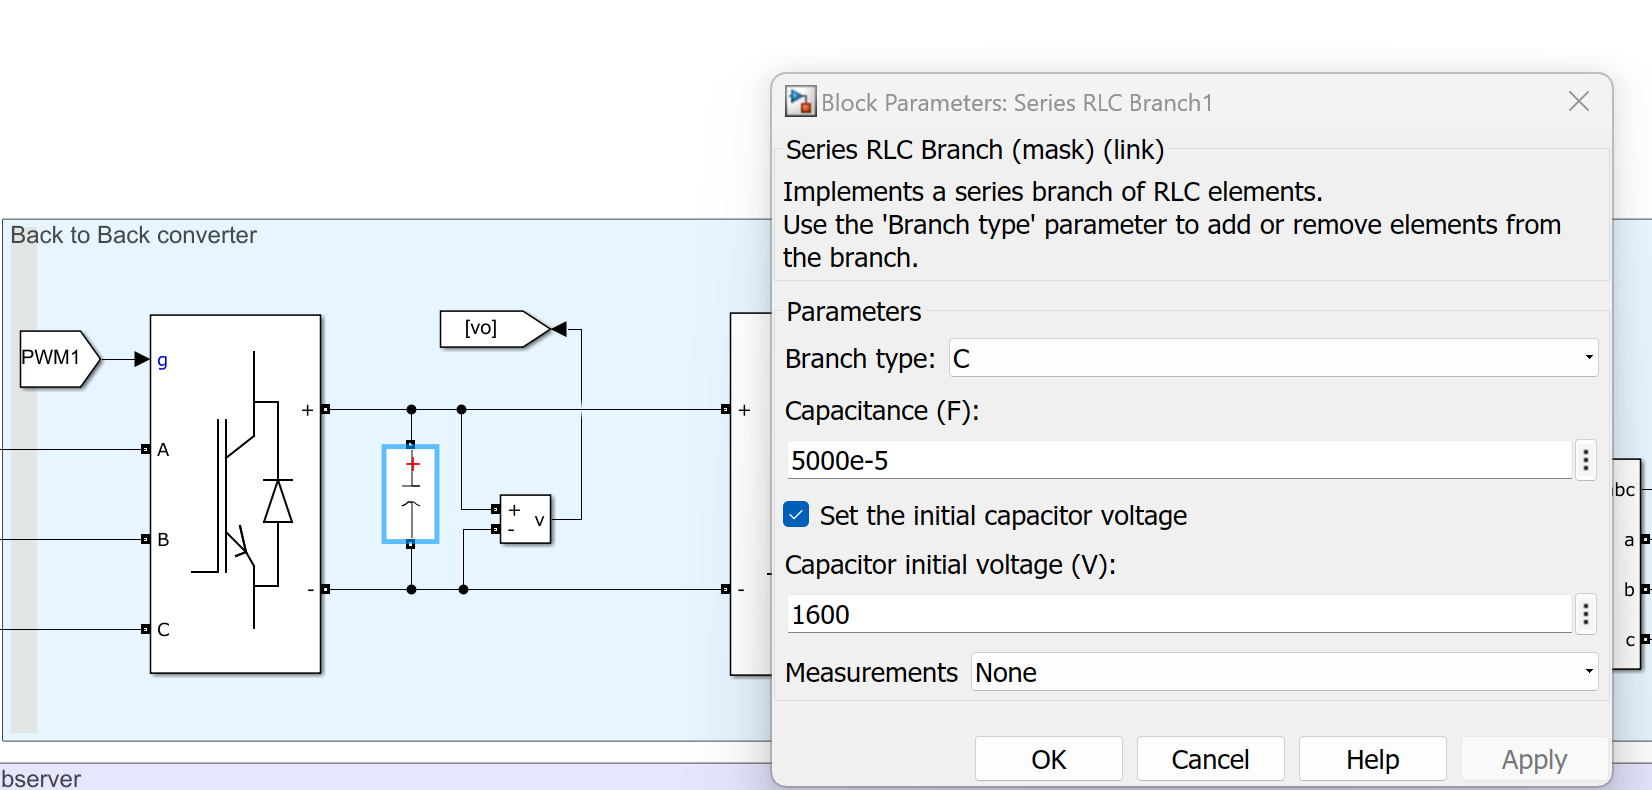

### 3.4. Reactive Power Control (Power Factor Control)

To operate at unity power factor, the q-axis current (Iq) reference is set to zero, as shown below:

Before changing the q-axis current reference, predict how the change will affect reactive power and power factor. Then adjust the reference and observe the effect.

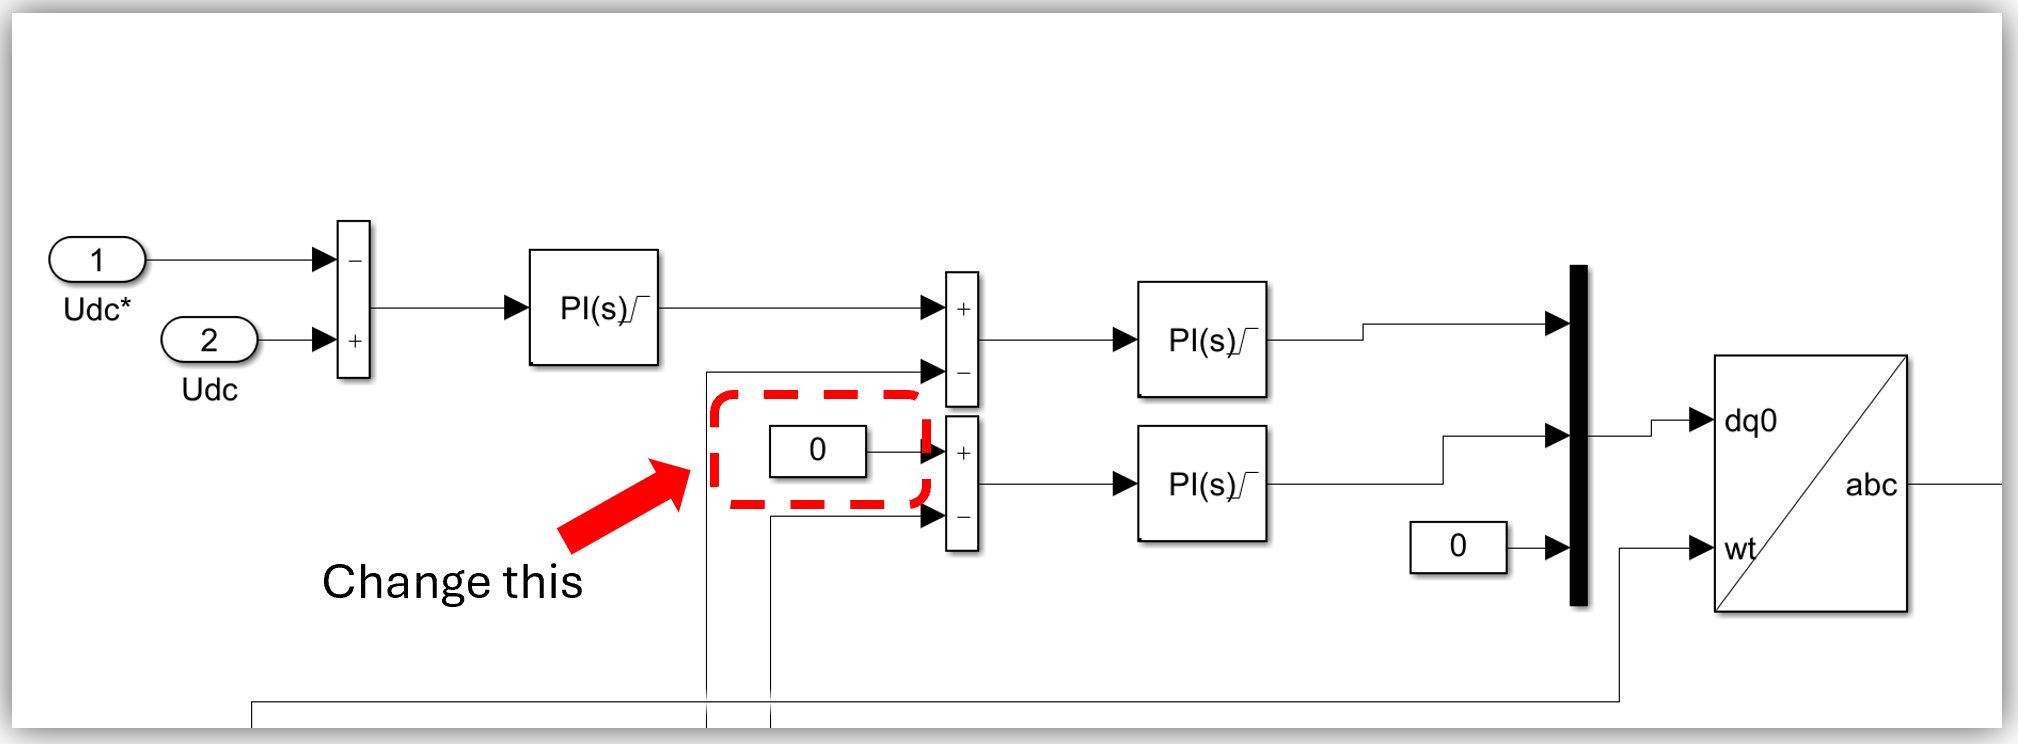

In reactive power control, setting the q-axis current to zero (with the d-axis aligned to the grid voltage) eliminates reactive power exchange between the converter and the grid, ensuring that all delivered power is purely active, the power factor is unity, and system efficiency and voltage stability are maintained.

**Question:** If the q-axis current reference is varied instead of fixed at zero, how can the converter be controlled to provide both active and reactive power simultaneously, and what would be the impact on power factor and system efficiency?

## 4. Example Simulation Results

This section shows reference responses for important system variables. Use them to check whether your simulation results have the expected trends.

result("No Selection")

## 5. Conclusion

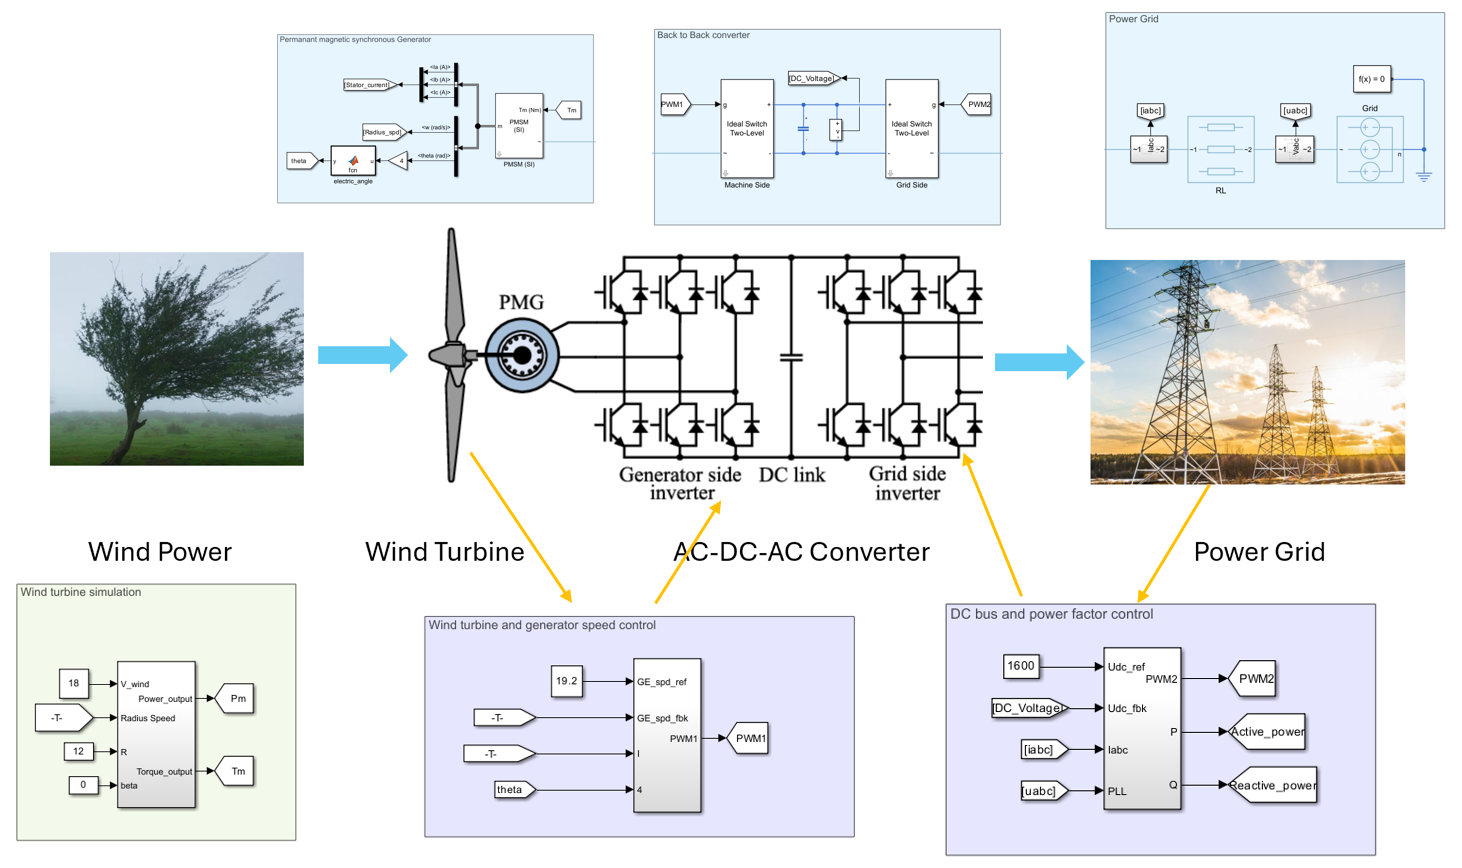

This model connects the main control blocks in a Type 4 PMSG wind power system: turbine behavior, generator speed control, DC-bus regulation, and reactive-power control. After completing this activity, you should be able to interpret the simulation responses and explain how each control loop contributes to reliable grid-connected wind energy conversion.

function switchRectifier(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "battery" "Grid" "LLC Converter" "Hbridge"])}
end
clf;
if opt == "No Selection"
else
    if opt == "battery"
        rect = imread("Images/OnBoardCharger/battery.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Grid"
        rect = imread("Images/OnBoardCharger/grid.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "LLC Converter"
        rect = imread("Images/OnBoardCharger/LLC.png");
        imshow(rect, 'Interpolation', 'bilinear');
    elseif opt == "Hbridge"
        rect = imread("Images/OnBoardCharger/Hbridge.png");
        imshow(rect, 'Interpolation', 'bilinear');
    end
end
end


function controller(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "DCbus control" "Inverter control" "SPWM"])}
end
clf;
if opt == "No Selection"
else
    if opt == "Inverter control"
        rect = imread("Images/OnBoardCharger/controller.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "SPWM"
        rect = imread("Images/OnBoardCharger/SPWM.png");
        imshow(rect,"Interpolation","bilinear");
    elseif opt == "DCbus control"
        rect = imread("Images/OnBoardCharger/dcbus.png");
        imshow(rect,"Interpolation","bilinear");
    end
end
end

function result(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "Constant Circuit" "Constant Voltage" "PowerGrid" "PowerFlow"])}
end
clf;
if opt == "No Selection"
else
    if opt == "Constant Circuit"
        rect = imread("Images/PMSGWindPowerSystem/Result1.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Constant Voltage"
        rect = imread("Images/PMSGWindPowerSystem/Result2.png");
        imshow(rect,"Interpolation","bilinear");
    elseif opt == "PowerGrid"
        rect = imread("Images/PMSGWindPowerSystem/Result3.png");
        imshow(rect,"Interpolation","bilinear");
    elseif opt == "PowerFlow"
        rect = imread("Images/PMSGWindPowerSystem/Result4.png");
        imshow(rect,"Interpolation","bilinear");
    end
end
end

function showpic1(A)
    arguments
        A (1,1) logical   
    end
    clf;
    if A
        rect = imread("Images/PMSGWindPowerSystem/CC.png");
        imshow(rect,'Interpolation',"bilinear");
    else 
    end
end

function showpic2(A)
    arguments
        A (1,1) logical   
    end
    clf;
    if A
        rect = imread("Images/OnBoardCharger/CV.png");
        imshow(rect,'Interpolation',"bilinear");
    else 
    end
end

function runmodel()
warning('off', 'all'); 
simOut = sim('Models/newnewPMSG.slx'); 
out=simOut;


ge_data = out.get('GE');
power_data = out.get('power');
wind_data = out.get('wind');
grid_data = out.get('Grid');


time = grid_data.time; 


signal1 = squeeze(grid_data.signals(1).values); 
signal2 = squeeze(grid_data.signals(2).values); 


signal3 = squeeze(ge_data.signals(1).values); 
signal4 = squeeze(ge_data.signals(2).values);


signal5 = squeeze(wind_data.signals(1).values); 
signal6 = squeeze(wind_data.signals(2).values);


signal7 = squeeze(power_data.signals(1).values); 
signal8 = squeeze(power_data.signals(2).values);


figure('Position', [100, 100, 1000, 800]); 


subplot(2,2,1); 
yyaxis left
plot(time, signal1, 'LineWidth', 1.5); 
hold on;
yyaxis right
plot(time, signal2, 'LineWidth', 1.5);
hold off;
xlim([0 max(simOut.tout)])
ylim([-300 300]) 
title('Grid Scope Output');
xlabel('Time (s)');
grid on;
ax = gca;
yyaxis(ax,'left')
ylabel('DC Voltage')
yyaxis(ax,'right')
ylabel('Current')

subplot(2,2,2); 
yyaxis left
plot(time, signal3, 'LineWidth', 1.5);
hold on;
ylim([-3000 1500]) 
yyaxis right
plot(time, signal4, 'LineWidth', 1.5);
hold off;
xlim([0 max(simOut.tout)])
ylim([0 30]) 
title('GE Scope Output');
xlabel('Time (s)');
grid on;
ax = gca;
yyaxis(ax,'left')
ylabel('Current')
yyaxis(ax,'right')
ylabel('Angle')


subplot(2,2,3); 
yyaxis left
plot(time, signal5, 'LineWidth', 1.5);
hold on;
yyaxis right
plot(time, signal6, 'LineWidth', 1.5);
hold off;
title('Wind Scope Output');
xlabel('Time (s)');
grid on;
xlim([0 max(simOut.tout)])
ax = gca;
yyaxis(ax,'left')
ylabel('Radius Speed')
yyaxis(ax,'right')
ylabel('Speed RPM')


subplot(2,2,4); 
yyaxis left
plot(time, signal7, 'LineWidth', 1.5);
hold on;
yyaxis right
plot(time, signal8, 'LineWidth', 1.5);
hold off;
ylim([0 12E4]);
title('Power Scope Output');
xlabel('Time (s)');
grid on;
xlim([0 max(simOut.tout)])
ax = gca;
yyaxis(ax,'left')
ylabel('Active Power')
yyaxis(ax,'right')
ylabel('Reactive Power')


end
